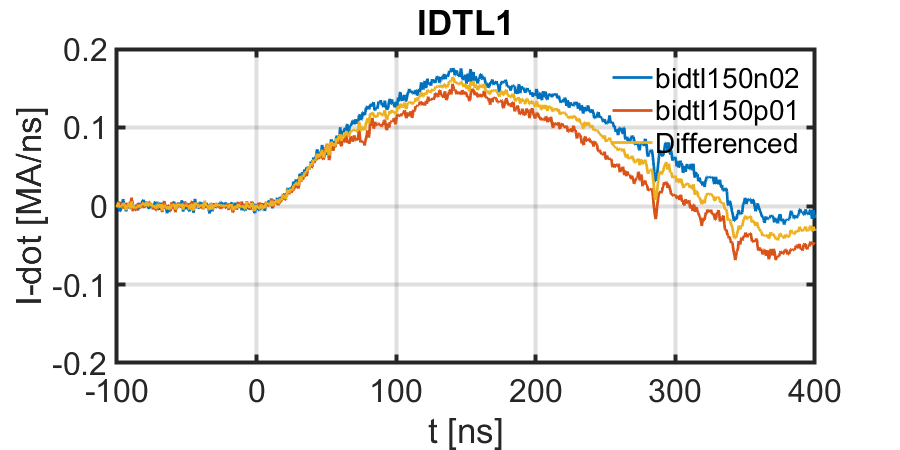

clc; close all; clear;

shot = 'z3697';

% Plot IDTL signals 

figure

inDir = checkDir('\Users\rdatta\Dropbox (MIT)\PUFFIN group\Data\Z\MARZ\Shots\MARZ1_z3697\Waveforms\shot3697_all_waveforms_ASCII\');

% IDTL 1

fname = 'bidtl150n02';
data = dlmread([inDir,fname]);
t = data(:,1)*1e9-2800;
V_n = data(:,2); % [A/s] (?)
% zero the signal
idx = (t < 0) & (t > -100);
V_n = V_n - mean(V_n(idx));


hold on;
plot(t,-1*V_n/1e6/1e9,linewidth=2, DisplayName = fname); hold on;


fname = 'bidtl150p01';
data = dlmread([inDir,fname]);
t = data(:,1)*1e9-2800;
V_p = data(:,2); % [A/s] (?)
% zero the signal
idx = (t < 0) & (t > -100);
V_p = V_p - mean(V_p(idx));

hold on;
plot(t,-1*V_p/1e6/1e9,linewidth=2, DisplayName = fname); hold on;

% effective signal
V_p = -1 * V_p;
V_idtl1 = 0.5 * (V_n - V_p); 

plot(t,-1*V_idtl1/1e6/1e9,linewidth=2, DisplayName = 'Differenced'); hold on;


ylim([-0.2,0.2])
xlabel('t [ns]'); ylabel('I-dot [MA/ns]')
grid();
xlim([-100,400])
formatPlots(900,2);
title('IDTL1')

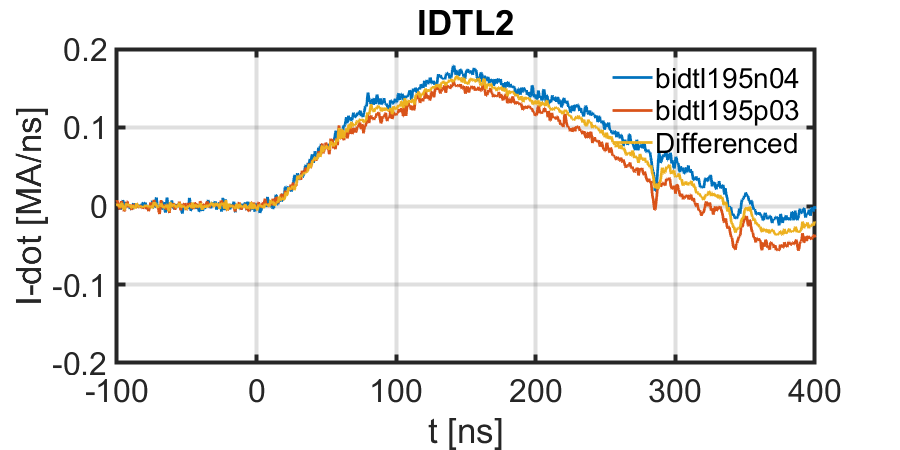

figure

% IDTL 2

fname = 'bidtl195n04';
data = dlmread([inDir,fname]);
t = data(:,1)*1e9-2800;
V_n = data(:,2); % [A/s] (?)
% zero the signal
idx = (t < 0) & (t > -100);
V_n = V_n - mean(V_n(idx));


hold on;
plot(t,-1*V_n/1e6/1e9,linewidth=2, DisplayName = fname); hold on;


fname = 'bidtl195p03';
data = dlmread([inDir,fname]);
t = data(:,1)*1e9-2800;
V_p = data(:,2); % [A/s] (?)
% zero the signal
idx = (t < 0) & (t > -100);
V_p = V_p - mean(V_p(idx));

hold on;
plot(t,-1*V_p/1e6/1e9,linewidth=2, DisplayName = fname); hold on;

% effective signal
V_idtl2 = 0.5 * (V_n + V_p); 

plot(t,-1*V_idtl2/1e6/1e9,linewidth=2, DisplayName = 'Differenced'); hold on;


ylim([-0.2,0.2])
xlabel('t [ns]'); ylabel('I-dot [MA/ns]')
grid();
xlim([-100,400])
formatPlots(900,2);
title('IDTL2')

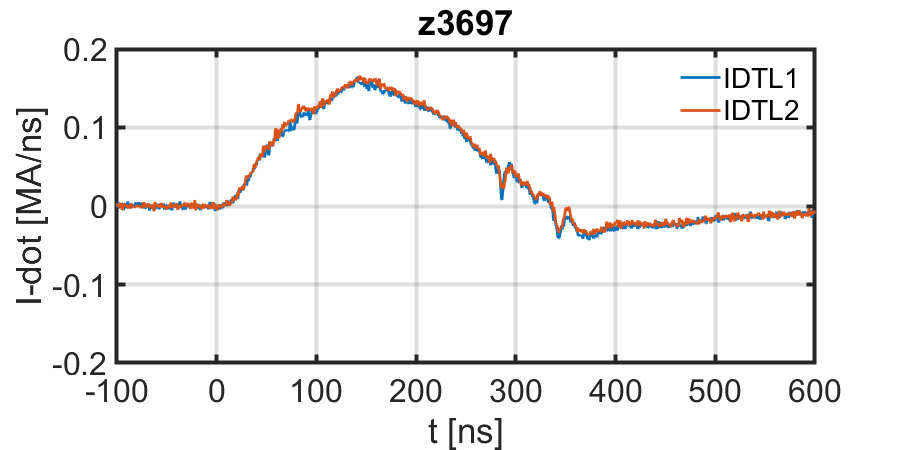


figure
% Plot both IDTL signals

plot(t,-1*V_idtl1/1e6/1e9,linewidth=2, DisplayName = 'IDTL1'); hold on;
plot(t,-1*V_idtl2/1e6/1e9,linewidth=2, DisplayName = 'IDTL2'); hold on;
ylim([-0.2,0.2])
xlabel('t [ns]'); ylabel('I-dot [MA/ns]')
title(shot)
grid();
xlim([-100,600])
formatPlots(900,2);

% save
saveDir = checkDir('\Users\rdatta\Dropbox (MIT)\PUFFIN\Data\MARZ\CurrentDiagnostics\IDTLs\');

save([saveDir,shot,'.mat'],'V_idtl1','V_idtl2','t');


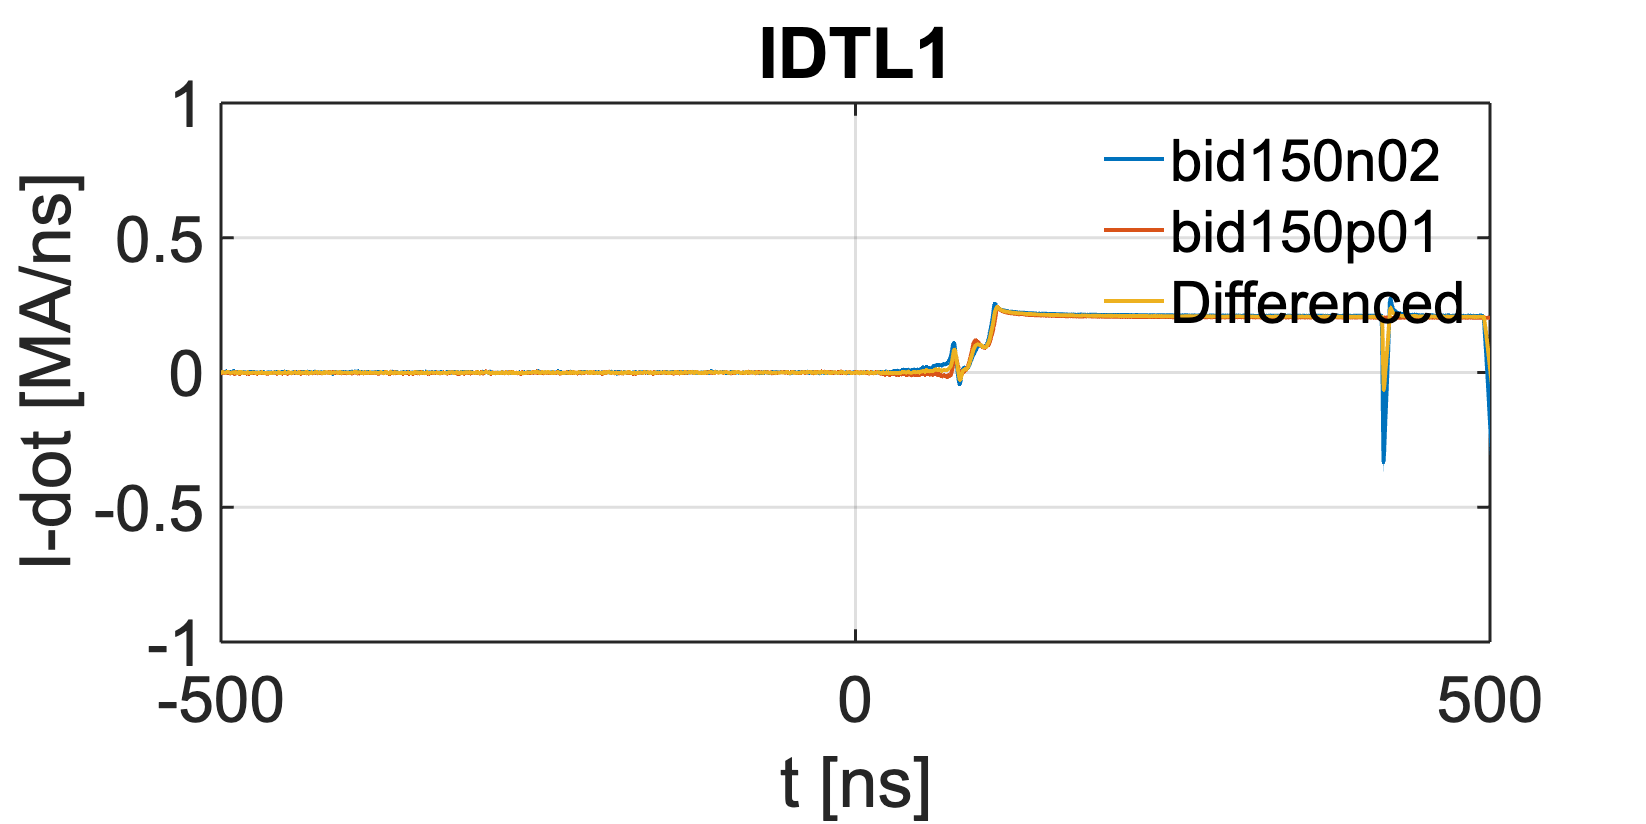

shot = 'z3781';

% Plot IDTL signals 

figure

inDir = checkDir('\Users\rdatta\Dropbox (MIT)\PUFFIN group\Data\Z\MARZ\Shots\MARZ3_z3781\IDTLs\');

% IDTL 1

fname = 'bid150n02';
data = dlmread([inDir,fname]);
t = data(:,1)*1e9-2800;
V_n = data(:,2); % [A/s] (?)
% zero the signal
idx = (t < 0) & (t > -100);
V_n = V_n - mean(V_n(idx));


hold on;
plot(t,-1*V_n/1e6/1e9,linewidth=2, DisplayName = fname); hold on;


fname = 'bid150p01';
data = dlmread([inDir,fname]);
t = data(:,1)*1e9-2800;
V_p = data(:,2); % [A/s] (?)
% zero the signal
idx = (t < 0) & (t > -100);
V_p = V_p - mean(V_p(idx));

hold on;
plot(t,-1*V_p/1e6/1e9,linewidth=2, DisplayName = fname); hold on;

% effective signal
V_idtl1 = 0.5 * (V_n + V_p); 

plot(t,-1*V_idtl1/1e6/1e9,linewidth=2, DisplayName = 'Differenced'); hold on;


ylim([-1,1])
xlabel('t [ns]'); ylabel('I-dot [MA/ns]')
grid();
xlim([-500,500])
formatPlots(900,2);
title('IDTL1')

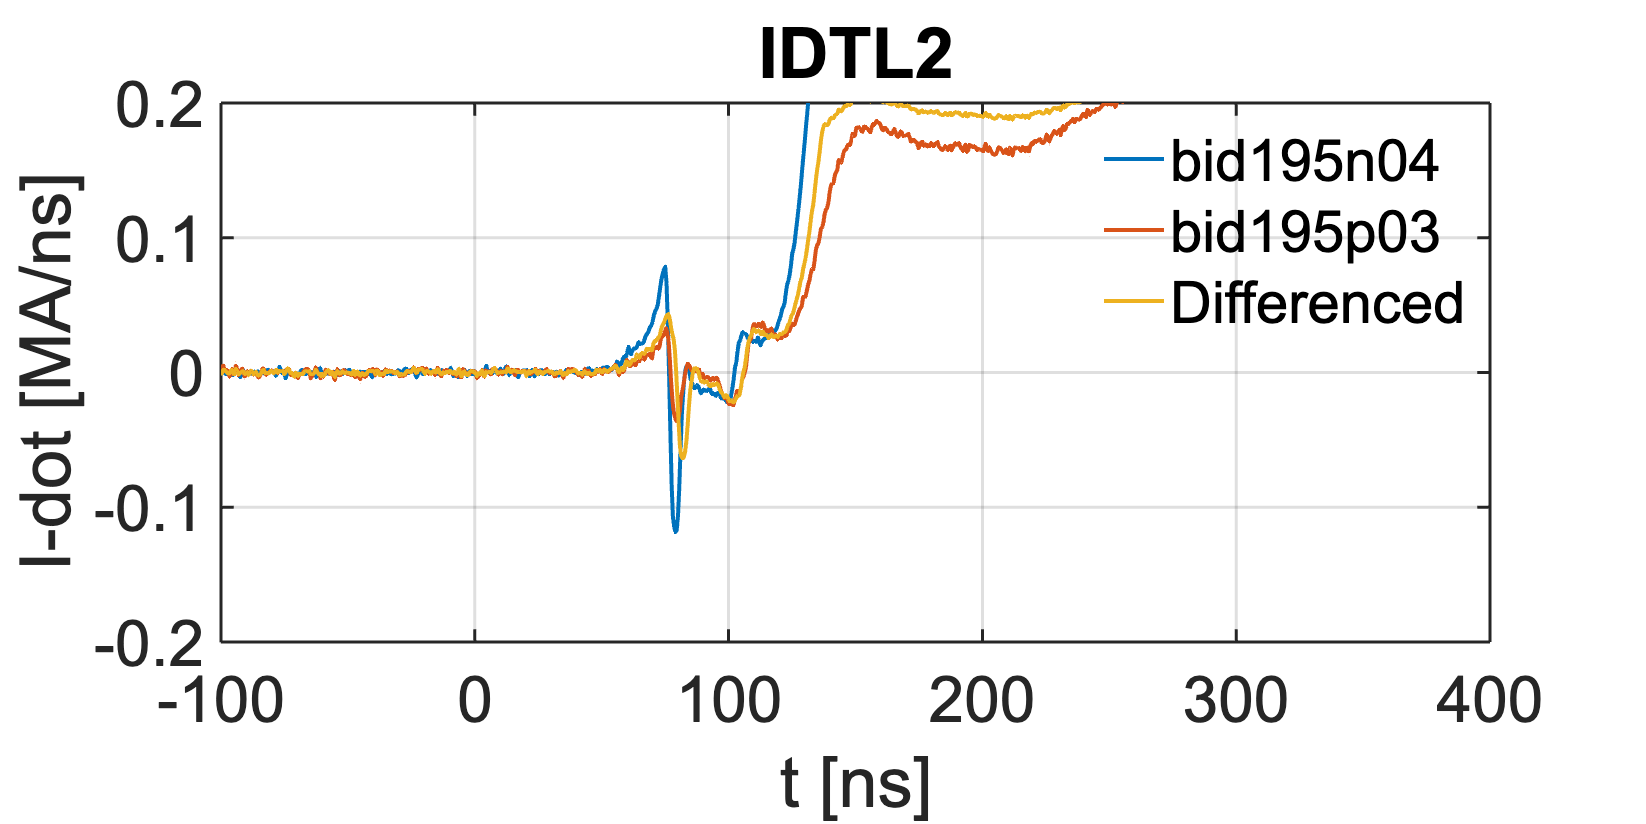

figure


% IDTL 2

fname = 'bid195n04';
data = dlmread([inDir,fname]);
t = data(:,1)*1e9-2800;
V_n = data(:,2); % [A/s] (?)
% zero the signal
idx = (t < 0) & (t > -100);
V_n = V_n - mean(V_n(idx));


hold on;
plot(t,-1*V_n/1e6/1e9,linewidth=2, DisplayName = fname); hold on;


fname = 'bid195p03';
data = dlmread([inDir,fname]);
t = data(:,1)*1e9-2800;
V_p = data(:,2); % [A/s] (?)
% zero the signal
idx = (t < 0) & (t > -100);
V_p = V_p - mean(V_p(idx));

hold on;
plot(t,-1*V_p/1e6/1e9,linewidth=2, DisplayName = fname); hold on;

% effective signal
V_idtl2 = 0.5 * (V_n + V_p); 

plot(t,-1*V_idtl2/1e6/1e9,linewidth=2, DisplayName = 'Differenced'); hold on;


ylim([-0.2,0.2])
xlabel('t [ns]'); ylabel('I-dot [MA/ns]')
grid();

xlim([-100,400])
formatPlots(900,2);
title('IDTL2')

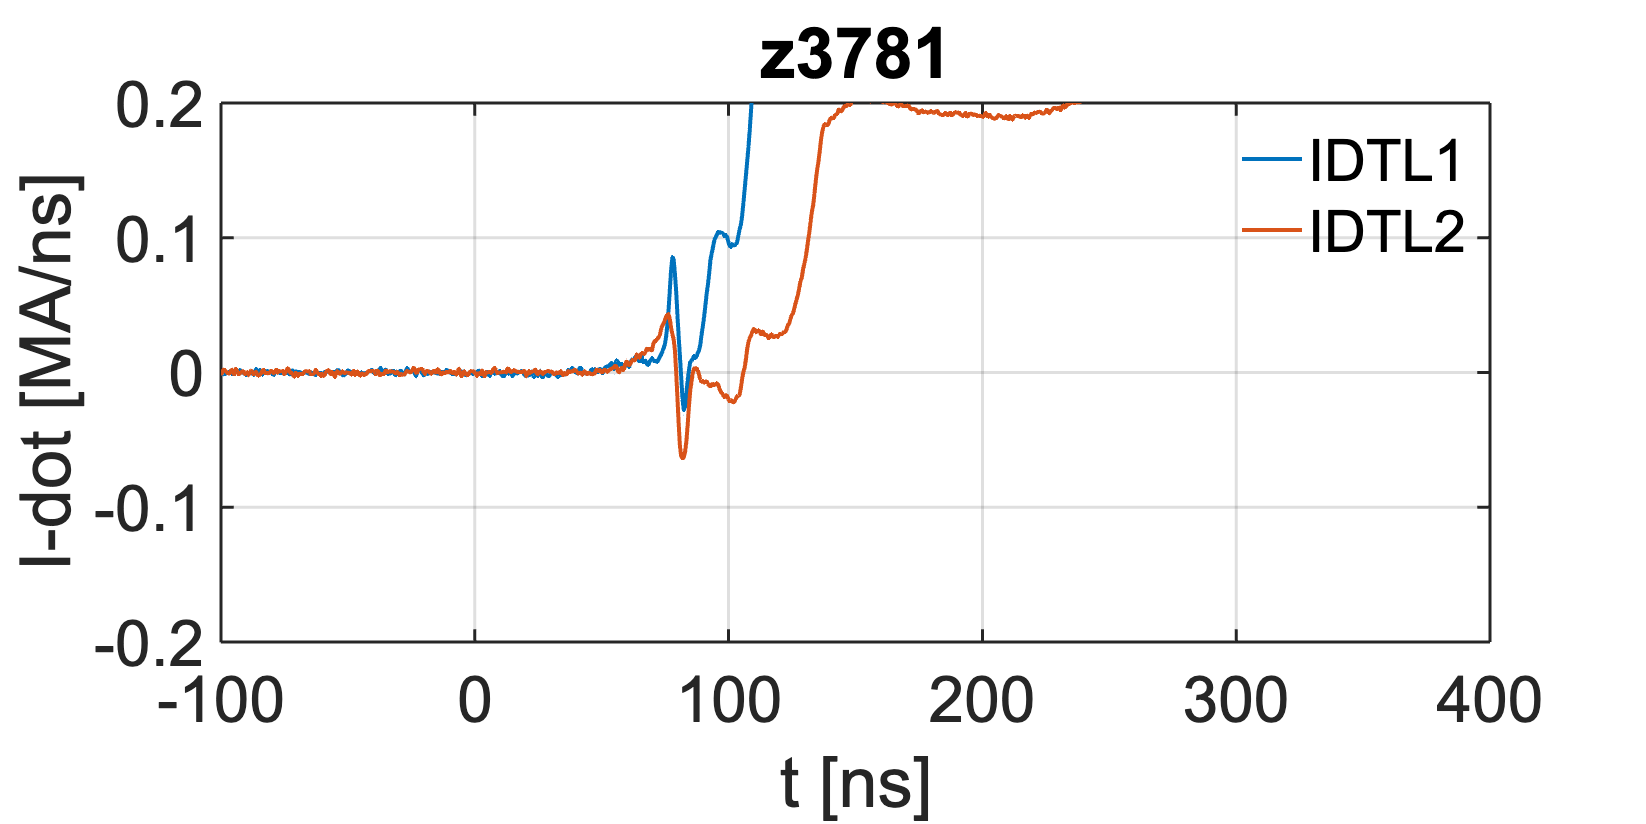


figure
% Plot both IDTL signals

plot(t,-1*V_idtl1/1e6/1e9,linewidth=2, DisplayName = 'IDTL1'); hold on;
plot(t,-1*V_idtl2/1e6/1e9,linewidth=2, DisplayName = 'IDTL2'); hold on;
ylim([-0.2,0.2])
xlabel('t [ns]'); ylabel('I-dot [MA/ns]')
grid();
title(shot)
xlim([-100,400])
formatPlots(900,2);

% save
saveDir = checkDir('\Users\rdatta\Dropbox (MIT)\PUFFIN\Data\MARZ\CurrentDiagnostics\IDTLs\');

save([saveDir,shot,'.mat'],'V_idtl1','V_idtl2','t');


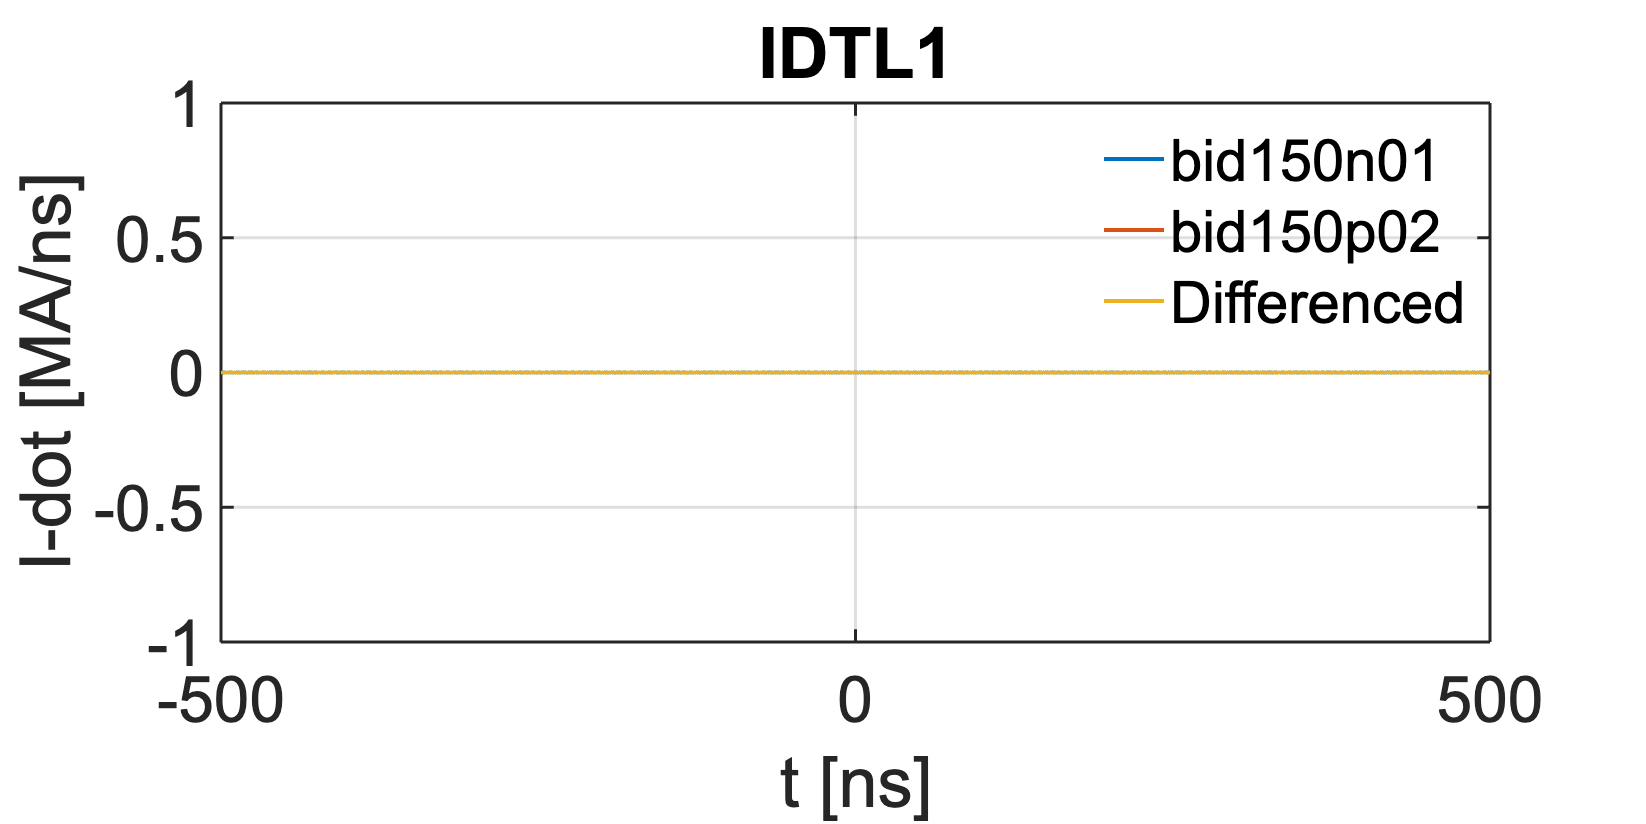

shot = 'z3778';

% Plot IDTL signals 

figure

inDir = checkDir('\Users\rdatta\Dropbox (MIT)\PUFFIN group\Data\Z\MARZ\Shots\MARZ2_z3778\IDTL signals\');

% IDTL 1

fname = 'bid150n01';
data = dlmread([inDir,fname]);
t = data(:,1)*1e9-2800;
V_n = data(:,2); % [A/s] (?)
% zero the signal
idx = (t < 0) & (t > -100);
V_n = V_n - mean(V_n(idx));


hold on;
plot(t,-1*V_n/1e6/1e9,linewidth=2, DisplayName = fname); hold on;


fname = 'bid150p02';
data = dlmread([inDir,fname]);
t = data(:,1)*1e9-2800;
V_p = data(:,2); % [A/s] (?)
% zero the signal
idx = (t < 0) & (t > -100);
V_p = V_p - mean(V_p(idx));

hold on;
plot(t,-1*V_p/1e6/1e9,linewidth=2, DisplayName = fname); hold on;

% effective signal
V_idtl1 = 0.5 * (V_n + V_p); 

plot(t,-1*V_idtl1/1e6/1e9,linewidth=2, DisplayName = 'Differenced'); hold on;


ylim([-1,1])
xlabel('t [ns]'); ylabel('I-dot [MA/ns]')
grid();
xlim([-500,500])
formatPlots(900,2);
title('IDTL1')

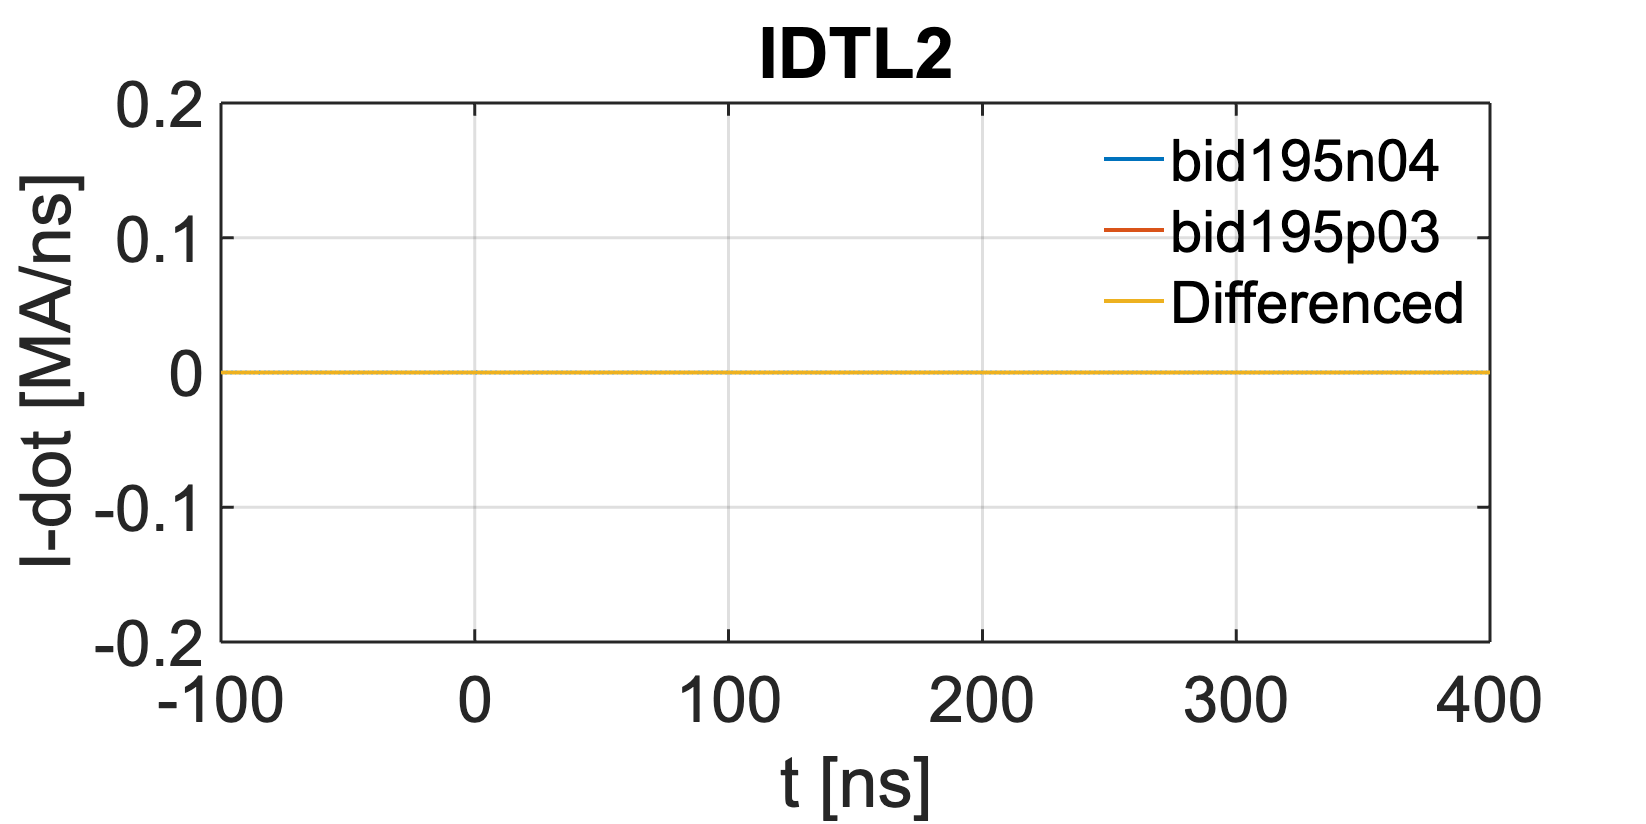

figure


% IDTL 2

fname = 'bid195n04';
data = dlmread([inDir,fname]);
t = data(:,1)*1e9-2800;
V_n = data(:,2); % [A/s] (?)
% zero the signal
idx = (t < 0) & (t > -100);
V_n = V_n - mean(V_n(idx));


hold on;
plot(t,-1*V_n/1e6/1e9,linewidth=2, DisplayName = fname); hold on;


fname = 'bid195p03';
data = dlmread([inDir,fname]);
t = data(:,1)*1e9-2800;
V_p = data(:,2); % [A/s] (?)
% zero the signal
idx = (t < 0) & (t > -100);
V_p = V_p - mean(V_p(idx));

hold on;
plot(t,-1*V_p/1e6/1e9,linewidth=2, DisplayName = fname); hold on;

% effective signal
V_idtl2 = 0.5 * (V_n + V_p); 

plot(t,-1*V_idtl2/1e6/1e9,linewidth=2, DisplayName = 'Differenced'); hold on;


ylim([-0.2,0.2])
xlabel('t [ns]'); ylabel('I-dot [MA/ns]')
grid();
xlim([-100,400])
formatPlots(900,2);
title('IDTL2')

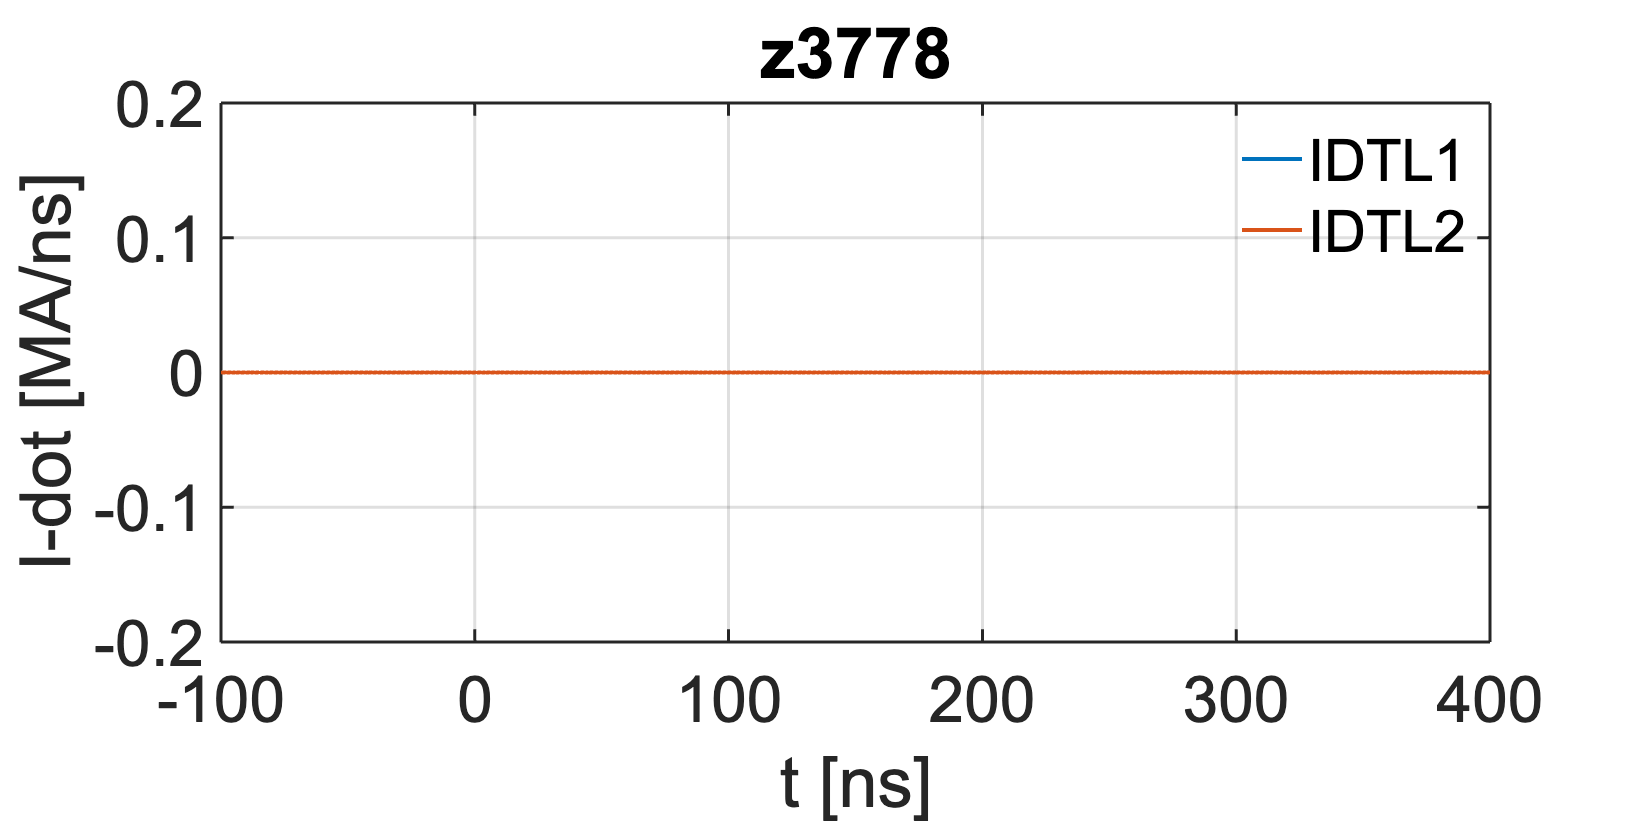


figure
% Plot both IDTL signals

plot(t,-1*V_idtl1/1e6/1e9,linewidth=2, DisplayName = 'IDTL1'); hold on;
plot(t,-1*V_idtl2/1e6/1e9,linewidth=2, DisplayName = 'IDTL2'); hold on;
ylim([-0.2,0.2])
title(shot)
xlabel('t [ns]'); ylabel('I-dot [MA/ns]')
grid();
xlim([-100,400])
formatPlots(900,2);

% save
saveDir = checkDir('\Users\rdatta\Dropbox (MIT)\PUFFIN\Data\MARZ\CurrentDiagnostics\IDTLs\');

save([saveDir,shot,'.mat'],'V_idtl1','V_idtl2','t');


# For POP

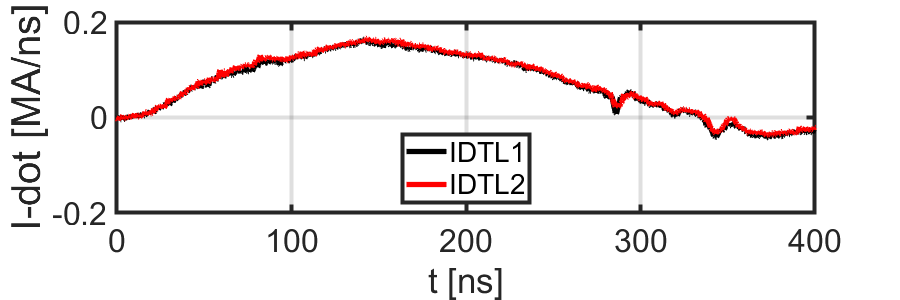


saveDir = checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/CurrentDiagnostics/IDTLs/');
shot = 'z3697';
load([saveDir,shot,'.mat'])


figure
% Plot both IDTL signals

plot(t,-1*V_idtl1/1e6/1e9,linewidth=4, DisplayName = 'IDTL1',color='k'); hold on;
plot(t,-1*V_idtl2/1e6/1e9,linewidth=4, DisplayName = 'IDTL2',color='r'); hold on;
ylim([-0.2,0.2])
xlabel('t [ns]'); 
grid();
xlim([0,400])
formatPlots(900,3);
ylabel('I-dot [MA/ns]',fontsize=30)
legend(Location='south',box='on');
saveDir = checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/Figures_POP/');
saveas(gcf,[saveDir,'z3697_IDTL.png']);

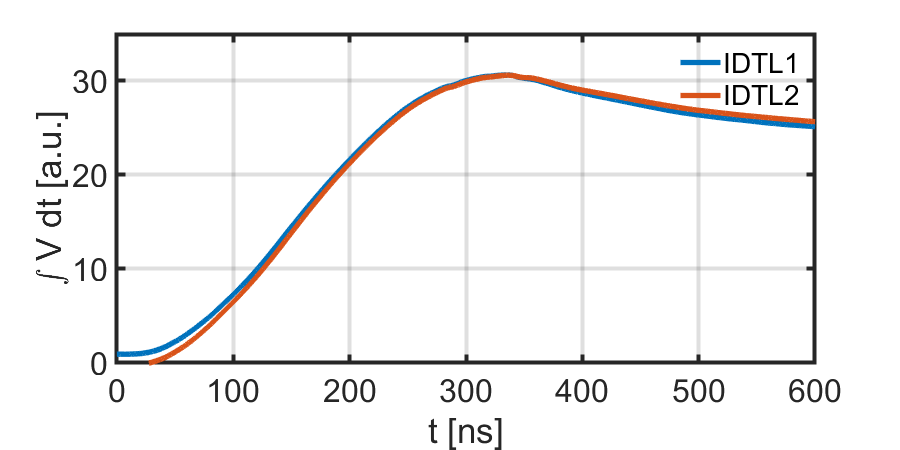

% integrate

I1 = cumtrapz(-1*V_idtl1/1e6/1e9) * min(diff(t));
I2 = cumtrapz(-1*V_idtl2/1e6/1e9) * min(diff(t));

% yyaxis right
% plot(t,I1,linewidth=4, DisplayName = 'IDTL1',color='k'); hold on;
% plot(t,I2,linewidth=4, DisplayName = 'IDTL2',color='r'); hold on;
% ylim([0,30])

figure
plot(t,I1,linewidth=4, DisplayName = 'IDTL1'); hold on;
plot(t,I2,linewidth=4, DisplayName = 'IDTL2'); hold on;
xlabel('t [ns]'); ylabel('\int V dt [a.u.]')
grid();
xlim([0,600])
formatPlots(900,2);
% legend('off');
ylim([0,35])